# 5.4. Эффект Доплера

#### Механические волны

*Источник S и наблюдатель O движутся по прямой линии (c>v_S, c>v_O)*

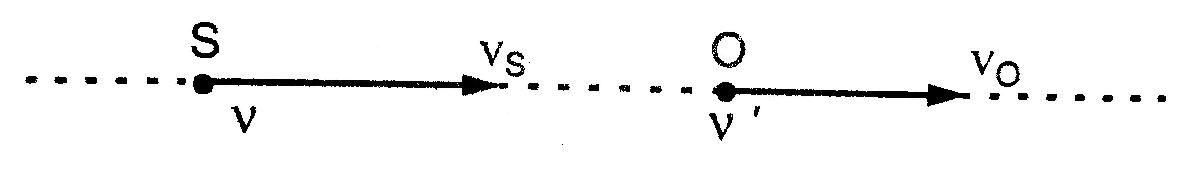

clear
digits(3)
syms c v_S v_O nu nu1
nu1==nu*(c-v_O)/(c-v_S)

$$ans = \nu_{1}=\frac{\nu \,\left(c-v_{O}\right)}{c-v_{S}}$$

% c = фазовая скорость в среде
% nu = частота источника
% v_S = скорость источника
% v_O = скорость наблюдателя

*S покоится, а O движется со скоростью v_O относительно среды (v_O<<c)*

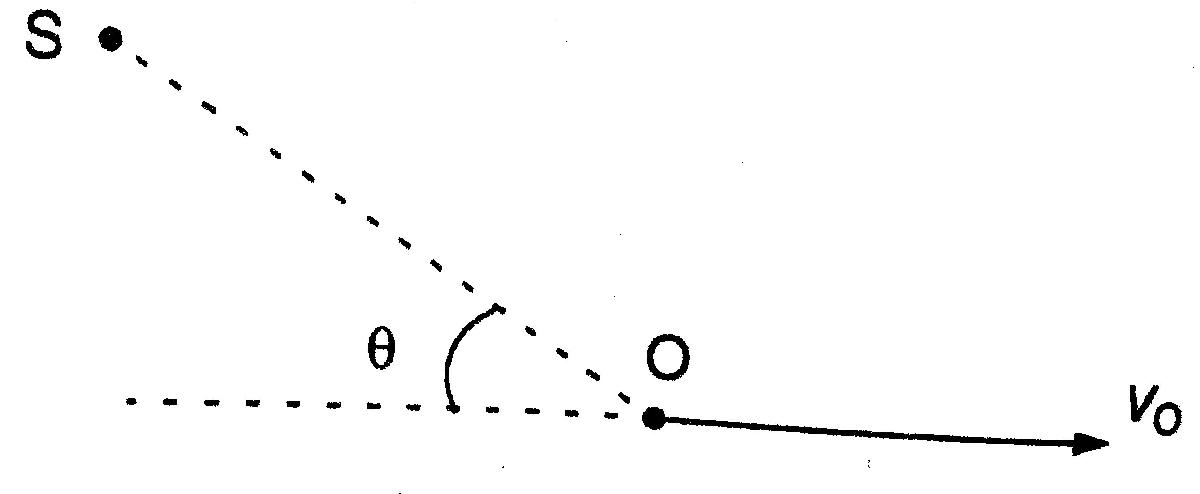

syms theta
nu1==nu*(1-v_O/c*cos(theta))

$$ans = \nu_{1}=-\nu \,\left(\frac{v_{O}\,\cos\left(\theta \right)}{c}-1\right)$$

*O покоится, а S движется со скоростью v_S относительно среды (v_O<<c)*

nu1==nu*(1+v_S/c*cos(theta))

$$ans = \nu_{1}=\nu \,\left(\frac{v_{S}\,\cos\left(\theta \right)}{c}+1\right)$$

Длина волны наблюдаемая O

syms lambda1 c nu1
lambda1==c/nu1

$$ans = \lambda_{1}=\frac{c}{\nu_{1}}$$

#### Электромагнитные волны

*Наблюдатель O1 движется со скоростью v=v*x относительно системы отсчета источника. O1 измеряет величины*

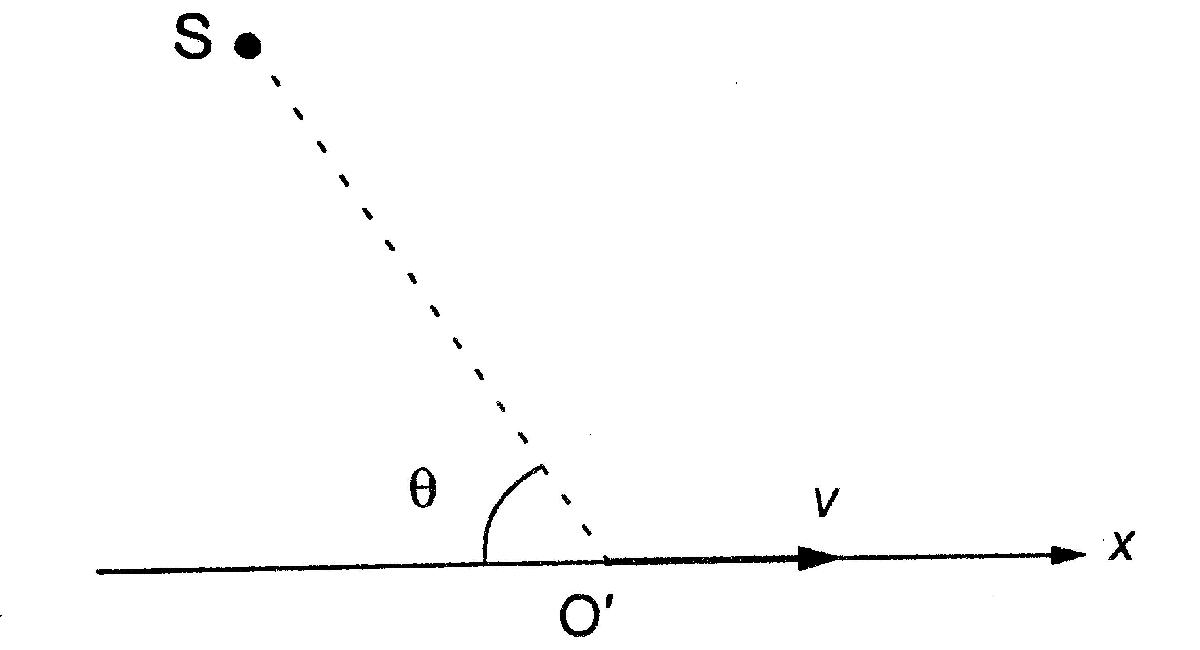

syms omega1 omega v c0 theta p1_x p_x E E1
omega1==omega*(1-v/c0*cos(theta))/sqrt(1-v^2/c0^2)

$$ans = \omega_{1}=-\frac{\omega \,\left(\frac{v\,\cos\left(\theta \right)}{c_{0}}-1\right)}{\sqrt{1-\frac{v^{2}}{{c_{0}}^{2}}}}$$

p1_x==(p_x-v*E/c0^2)/sqrt(1-v^2/c0^2)

$$ans = p_{1,x}=\frac{p_{x}-\frac{\text{E}\,v}{{c_{0}}^{2}}}{\sqrt{1-\frac{v^{2}}{{c_{0}}^{2}}}}$$

E1==(E-v*p_x)/sqrt(1-v^2/c0^2)

$$ans = E_{1}=\frac{\text{E}-p_{x}\,v}{\sqrt{1-\frac{v^{2}}{{c_{0}}^{2}}}}$$

% p = волновой импульс (система отсчета источника)
syms p_x p theta p1_x p1 theta1
p_x==p*cos(theta)

$$ans = p_{x}=p\,\cos\left(\theta \right)$$

p1_x==p1*cos(theta1)

$$ans = p_{1,x}=p_{1}\,\cos\left(\theta_{1}\right)$$

В частности, если источник S и наблюдатель O1 движутся прямолинейно друг от друга

cos(theta)==1

$$ans = \cos\left(\theta \right)=1$$

syms k1 k omega v c0
k1==(k-omega*v/c0^2)/sqrt(1-v^2/c0^2)

$$ans = k_{1}=\frac{k-\frac{\omega \,v}{{c_{0}}^{2}}}{\sqrt{1-\frac{v^{2}}{{c_{0}}^{2}}}}$$

% p, k omega, E и theta = величины, измеренные наблюдателем O,
% покоящимися относительно S и находящимся вблизи O1

*Связь theta  и theta1 (аберрация)*

cos(theta1)==(cos(theta)-v/c0)/(1-v/c0*cos(theta))

$$ans = \cos\left(\theta_{1}\right)=-\frac{\cos\left(\theta \right)-\frac{v}{c_{0}}}{\frac{v\,\cos\left(\theta \right)}{c_{0}}-1}$$

*Если источник S движется со скоростью v относительно системы отчета наблюдателя, с точки зрения O1 частота будет*

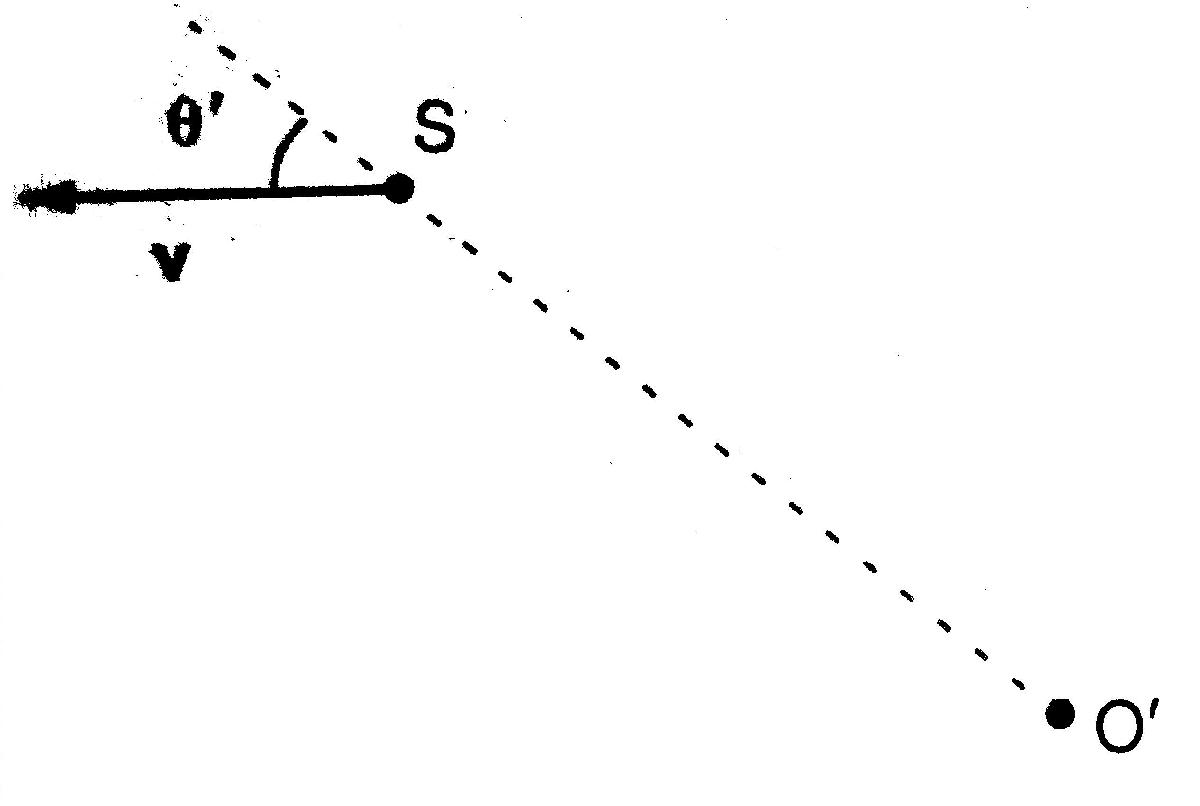

nu1==nu*sqrt(1-v^2/c0^2)/(1+v/c0*cos(theta1))

$$ans = \nu_{1}=\frac{\nu \,\sqrt{1-\frac{v^{2}}{{c_{0}}^{2}}}}{\frac{v\,\cos\left(\theta_{1}\right)}{c_{0}}+1}$$

% nu = частота источника

#### Доплеровское уширение спектральных линий

syms Dnu nu c0 R T M Delta(x)
Delta(nu)/nu==4*pi/c0*sqrt(2*R*T*log(sym(2))/M)==vpa(7.16e-7)*sqrt(T/M)

$$ans = \left(\frac{\Delta \left(\nu \right)}{\nu }=\frac{4\,\pi \,\sqrt{2}\,\sqrt{\frac{R\,T\,\log\left(2\right)}{M}}}{c_{0}}\right)=7.16e-7\,\sqrt{\frac{T}{M}}$$

% M = молекулярная масса (кг/моль)
% T = температура (кельвин)
% R = универсальная газовая постоянная